clear
% Specify the file path of the multi-page TIFF
%test synchrony2
aaaa
tic
% file_path = '/Users/platel/Desktop/exp/Sofia/ani55/mc_concat_reca_940_92um-001-_grid_13_factor.tif';
% path='/Users/platel/Desktop/exp/Sofia/ani55/';
file_path='/Users/platel/Desktop/exp/Sofia/mc_tiff_downs_6.5_10_um.tif';


% Read the multi-page TIFF
info = imfinfo(file_path);  % Get TIFF file information
num_pages = numel(info);    % Get the number of pages
height=info.Height;
width=info.Width;
size_pixel=10;

image_data = cell(1, num_pages);
intensity=zeros(height,width,num_pages);
% Read each page of the TIFF
for page = 1:num_pages
    % image_data{page} = imread(file_path, 'Index', page);
    % intensity(page,:,:)=cell2mat(image_data(page));
    intensity(:,:,page)=imread(file_path, 'Index', page);
end
% imread('/Users/platel/Desktop/exp/Sofia/ani55/mc_concat_reca_940_92um-001-_grid_13_factor.tif')
toc

Elapsed time is 2.984788 seconds.


%crop image
intensity=intensity(3:53,3:53,:);
[width, height,nt]=size (intensity);
NCell=width*height;
F=double(reshape(intensity(:,:,:),NCell,nt));

%Fluo=double(reshape(intensity,6241,18000));
F=F./median(F,2);
% speed =smoothdata(speed,'gaussian',50);

%bleaching correction
% for k = 1:NCell
%     F(k, :) = detrend(F(k,:),'Continuous',false);
% end
% disp('bleaching correction')
%traces=Fluo;
% Savitzky-Golay filter
 F = sgolayfilt(F',3,5)';
% intensity=cell2mat(image_data);

% Fr=double(F./median(F,2));
% Fr = sgolayfilt(Fr',3,7)';
% K = 10;
% L = 50;
% lambda =.005;
% [W, H, cost,loadings,power] = seqNMF(Tr1b,K,L,lambda)

% 
% plot (Fluo(100,:))
% hold on
% plot (traces(100,:))
% hold off

% Set parameters
tic
num_components = 14;  % number of components to extract
num_iterations = 10;  % number of iterations for the NMF algorithm

% Perform NMF
options = statset('UseParallel', true,'MaxIter',100);

[W, H , D] = nnmf(F, num_components, 'algorithm', 'als', 'replicates', num_iterations, 'options', options);

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 4 5 18 20 22 23 27 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 8 workers.


toc

Elapsed time is 53.748950 seconds.


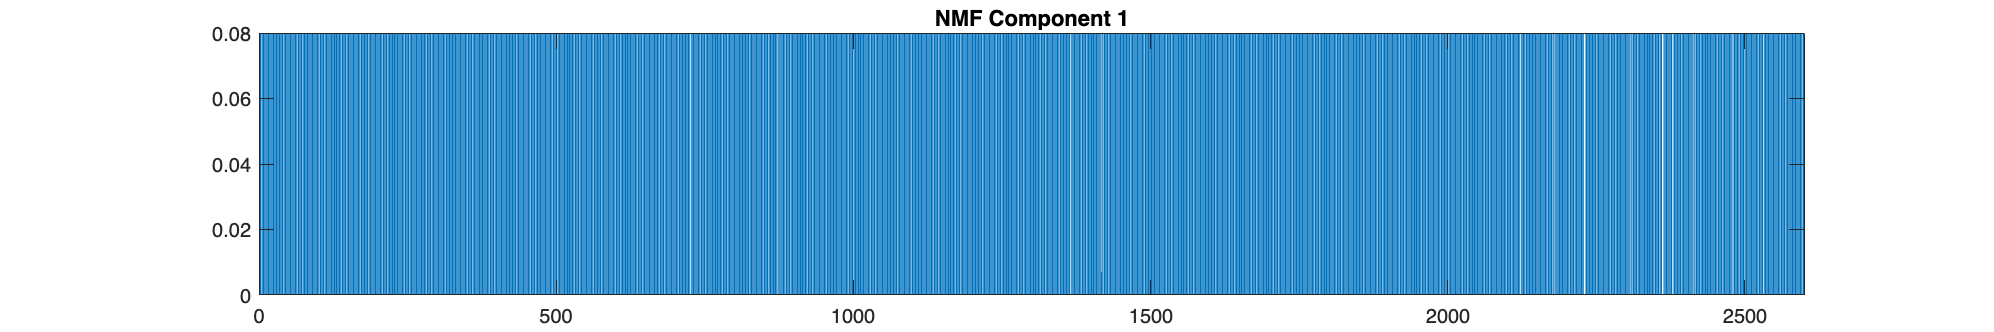

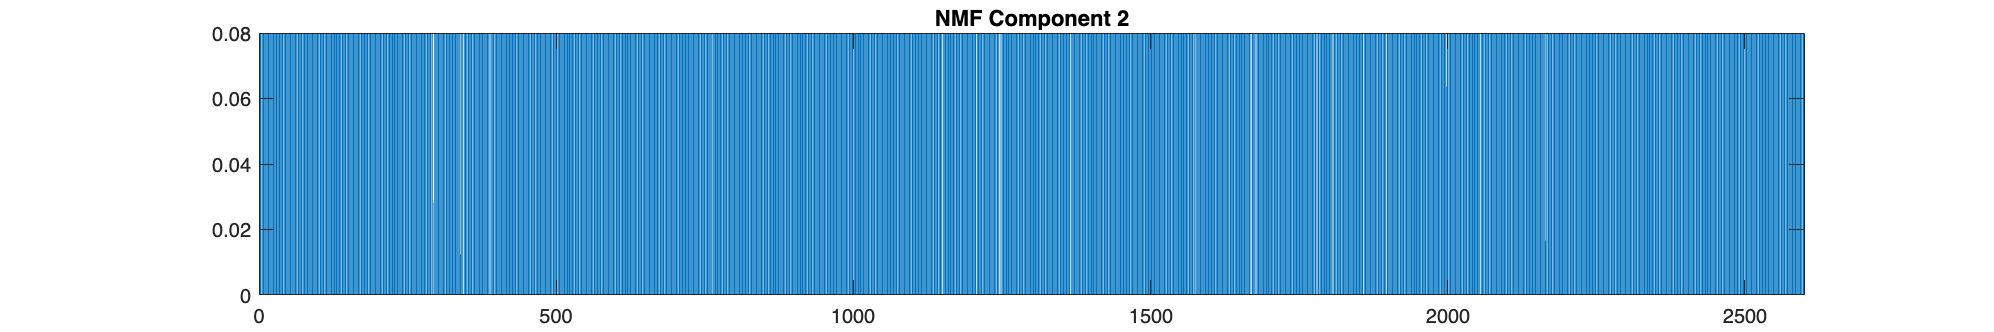

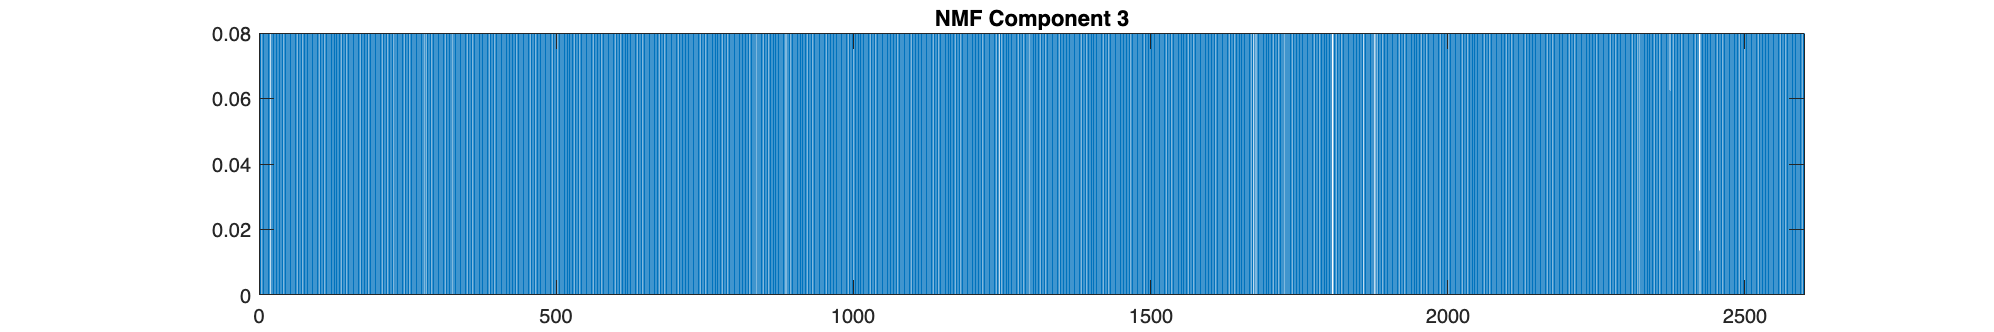

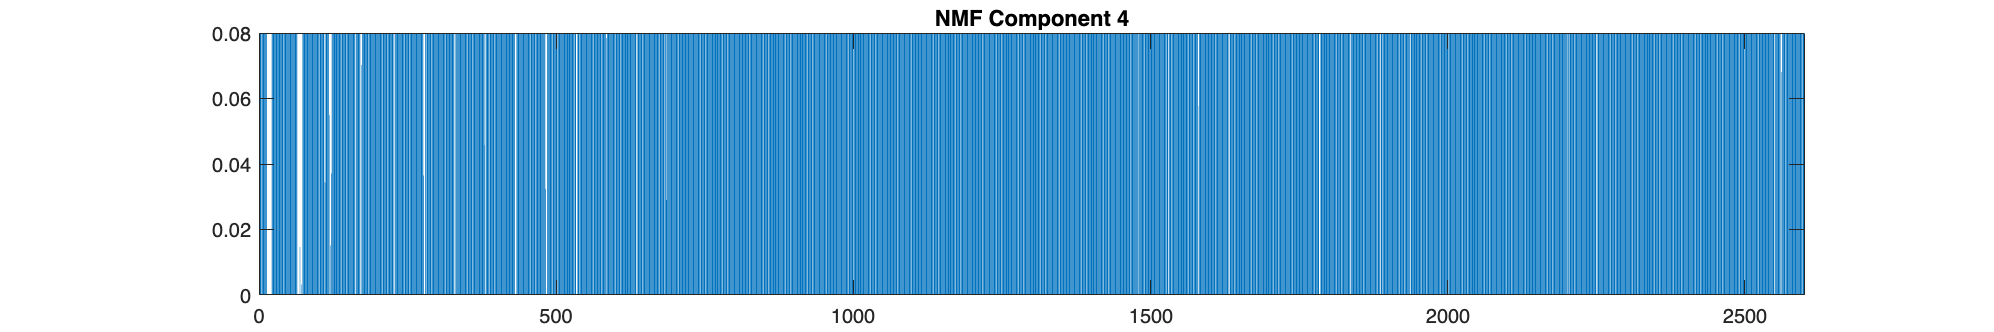

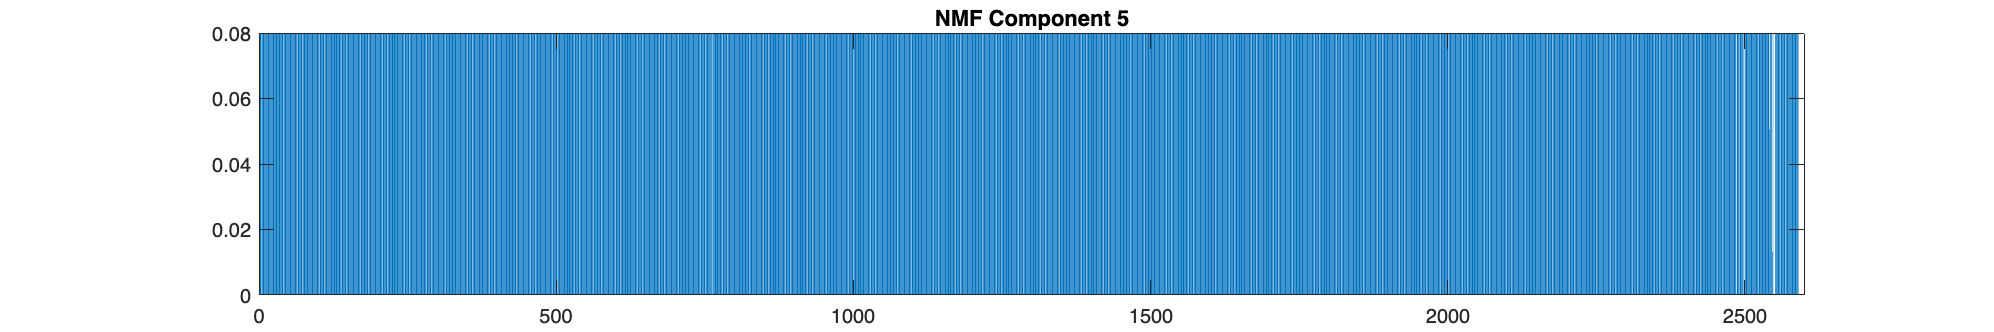

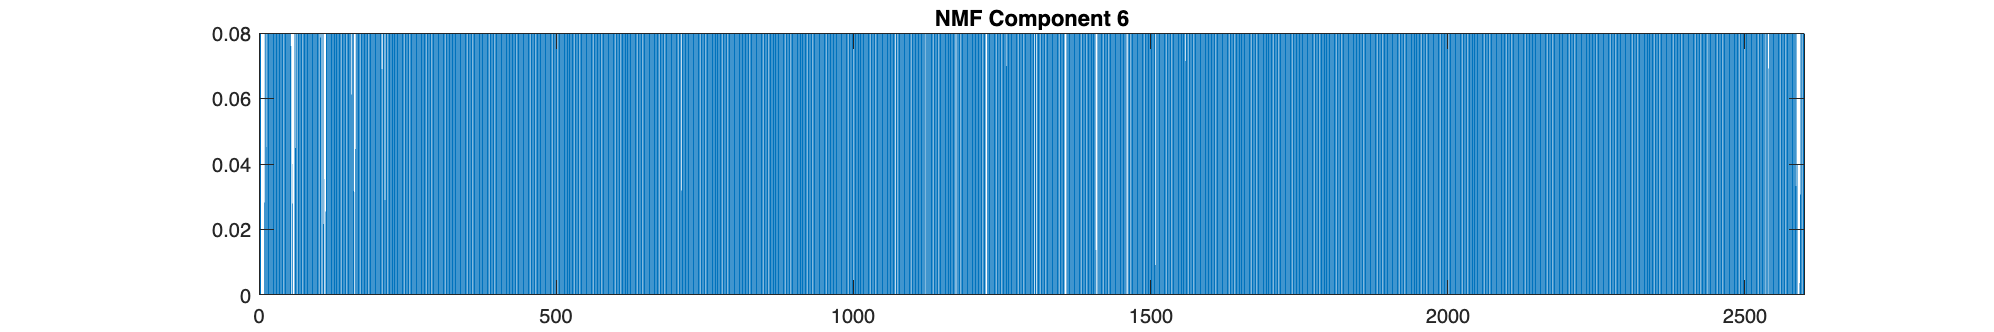

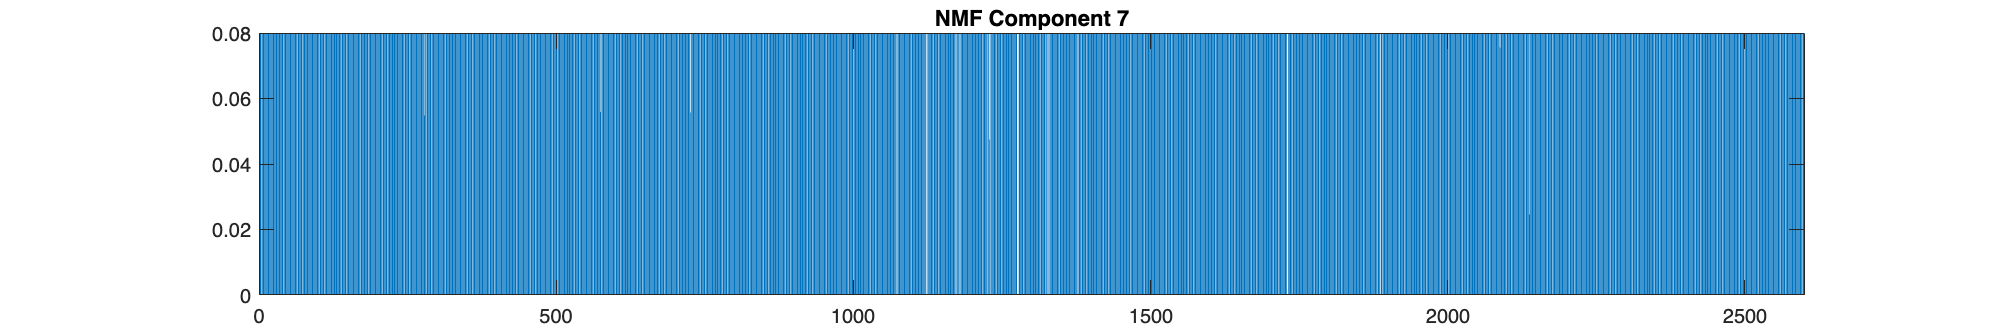

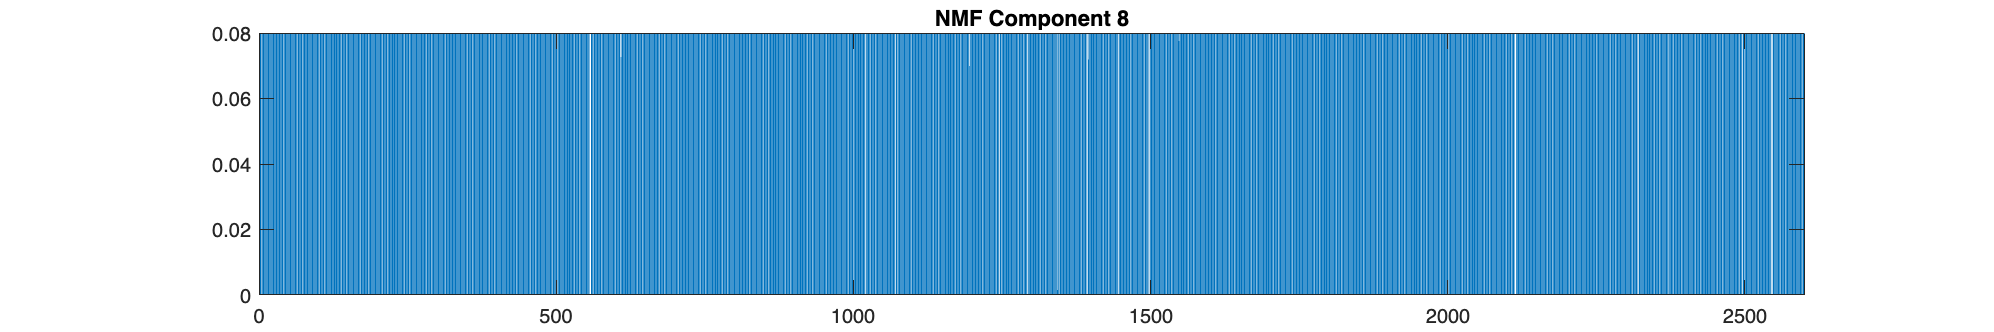


% Plot the NMF components
figure;

for i = 1:num_components

    figure
    set(gcf,'position',[0,0,1200,200])
    bar(W(:,i));
    title(['NMF Component ', num2str(i)]);
    axis ([0 NCell 0 0.5])

end

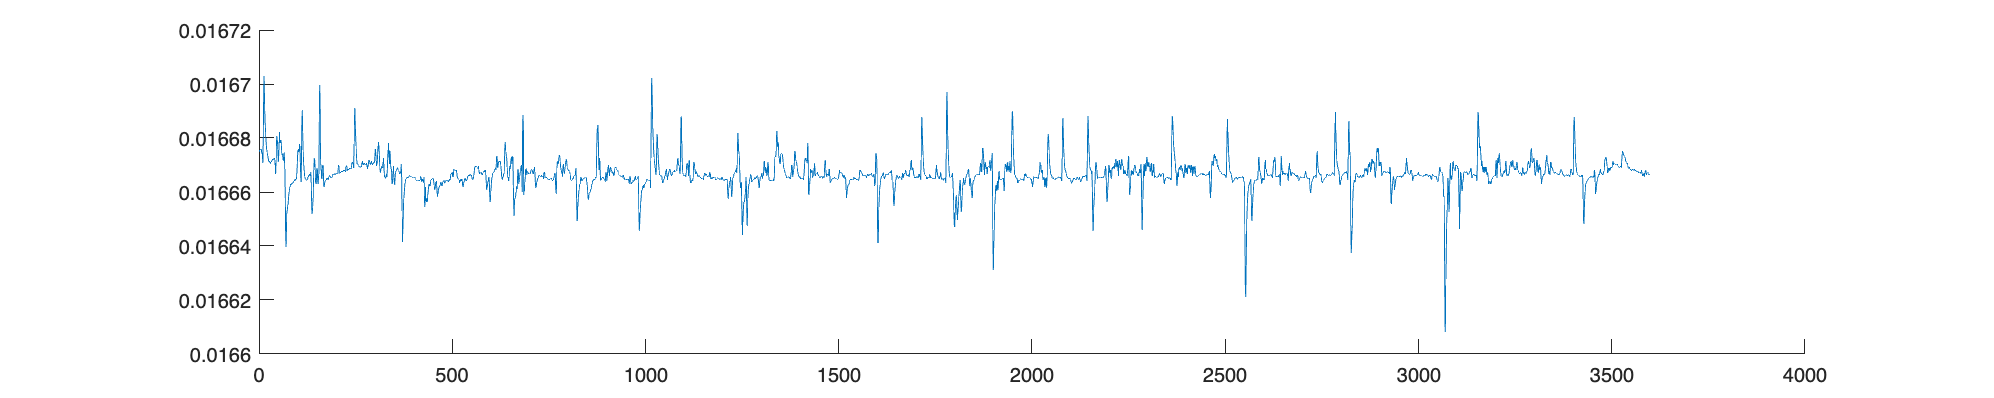

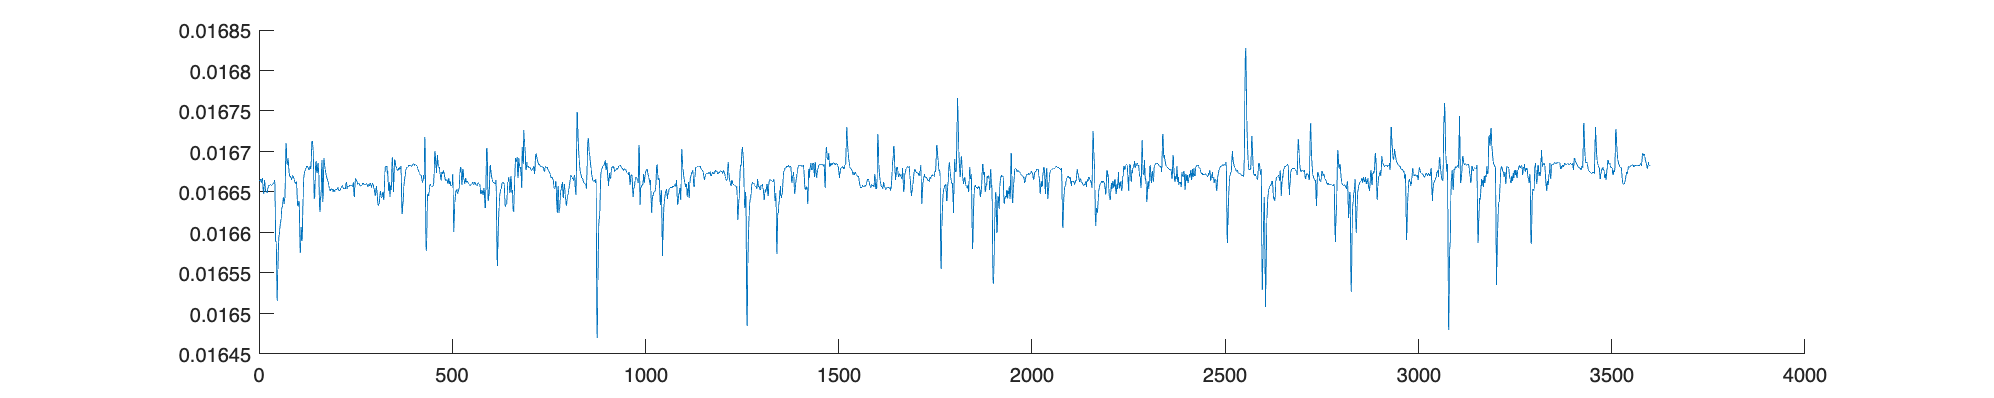

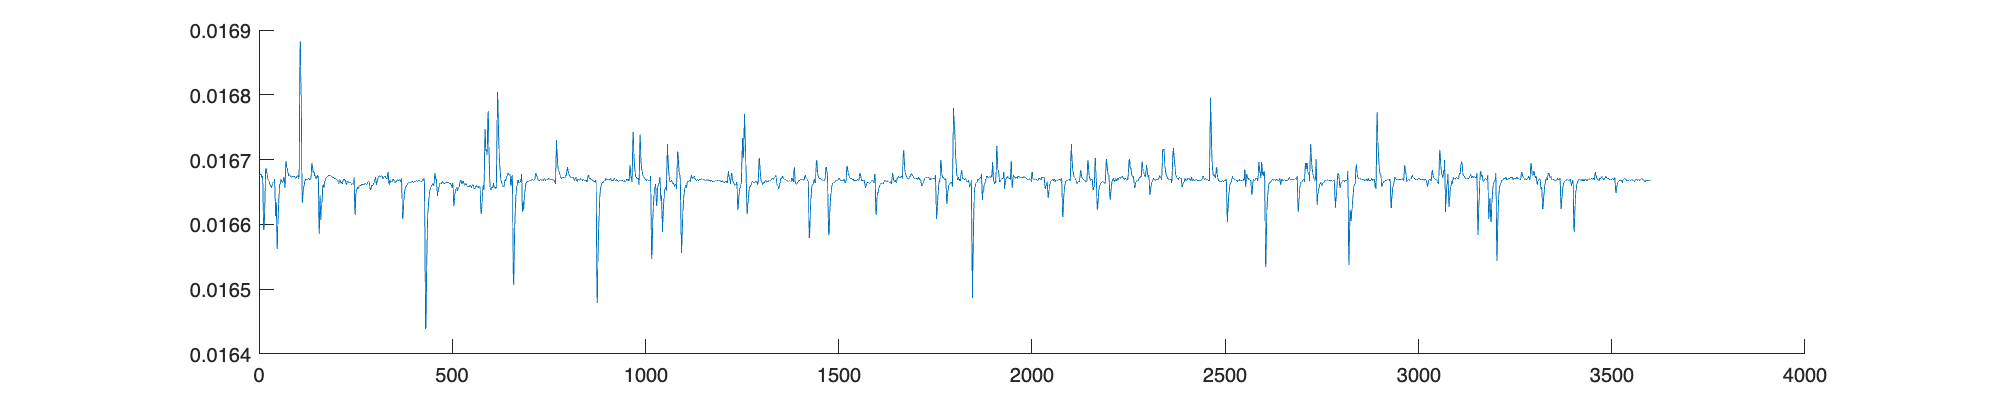

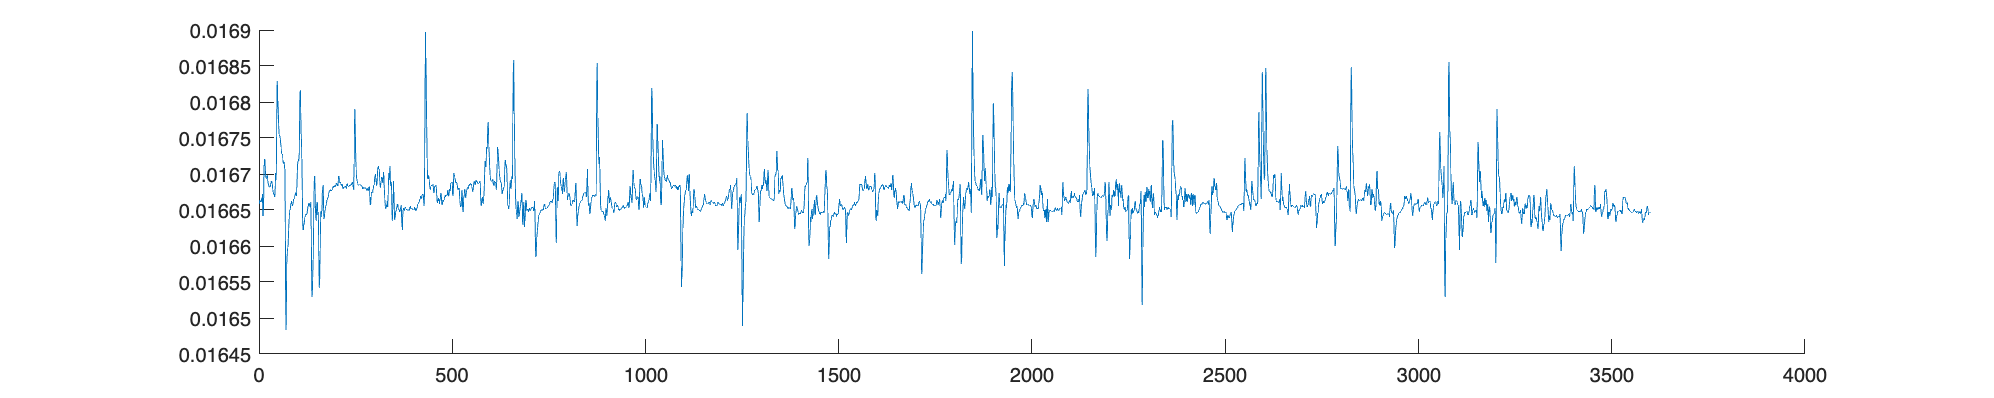

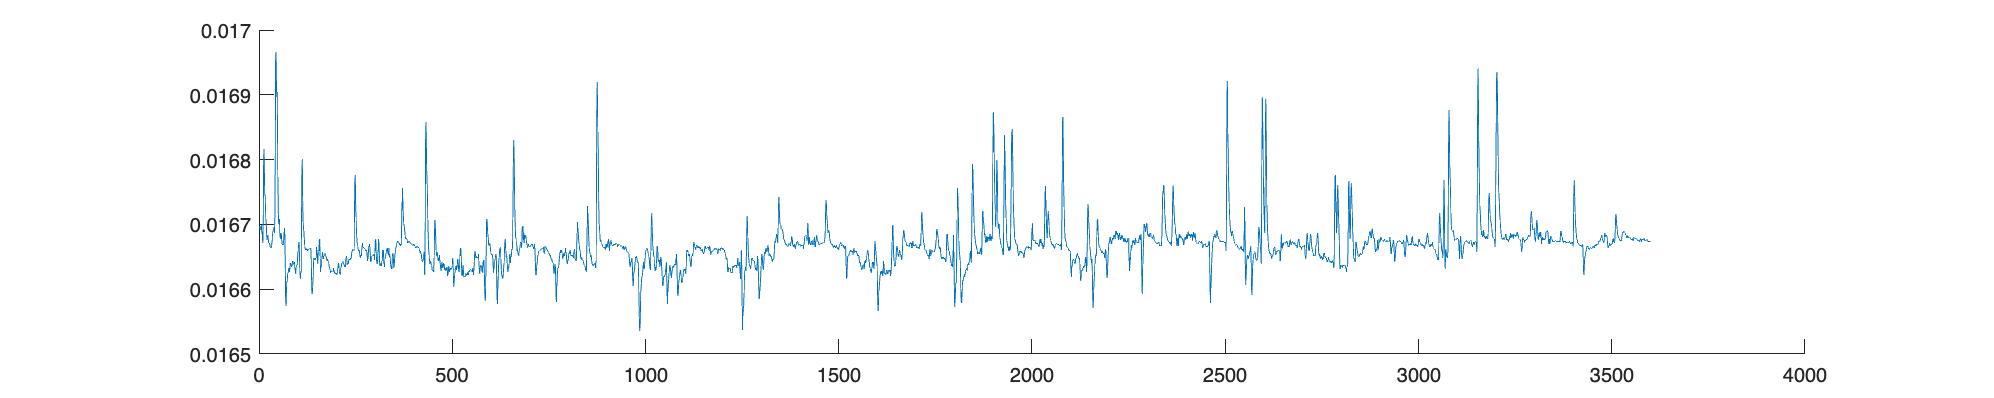

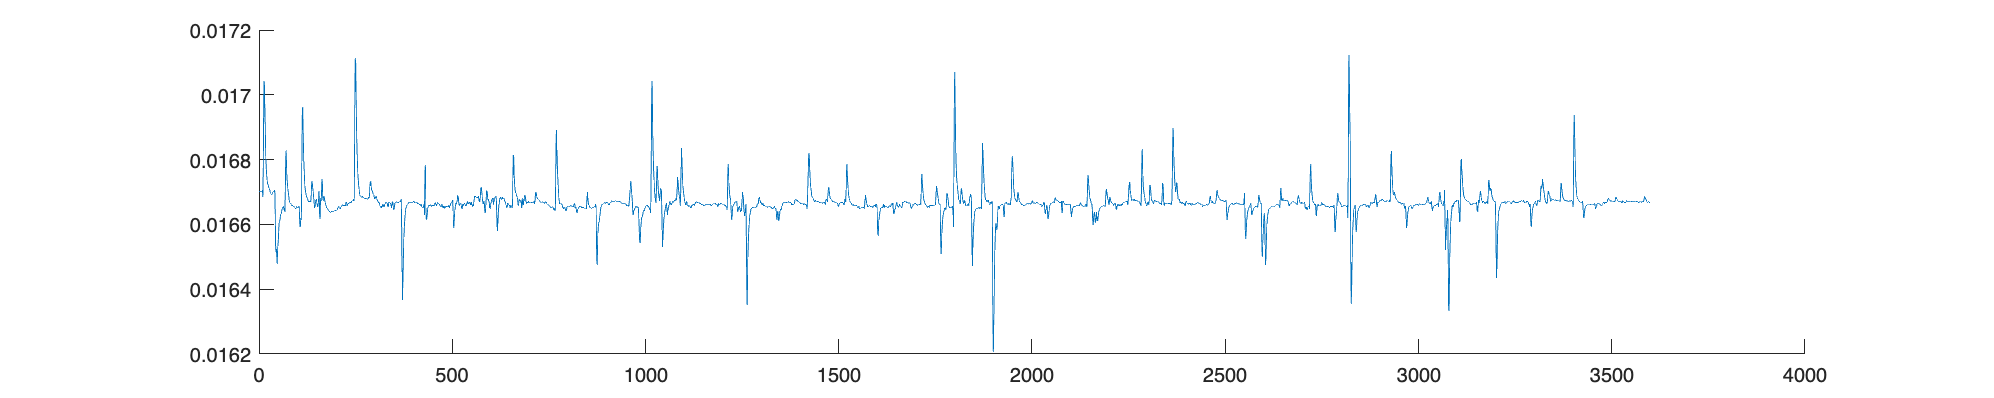

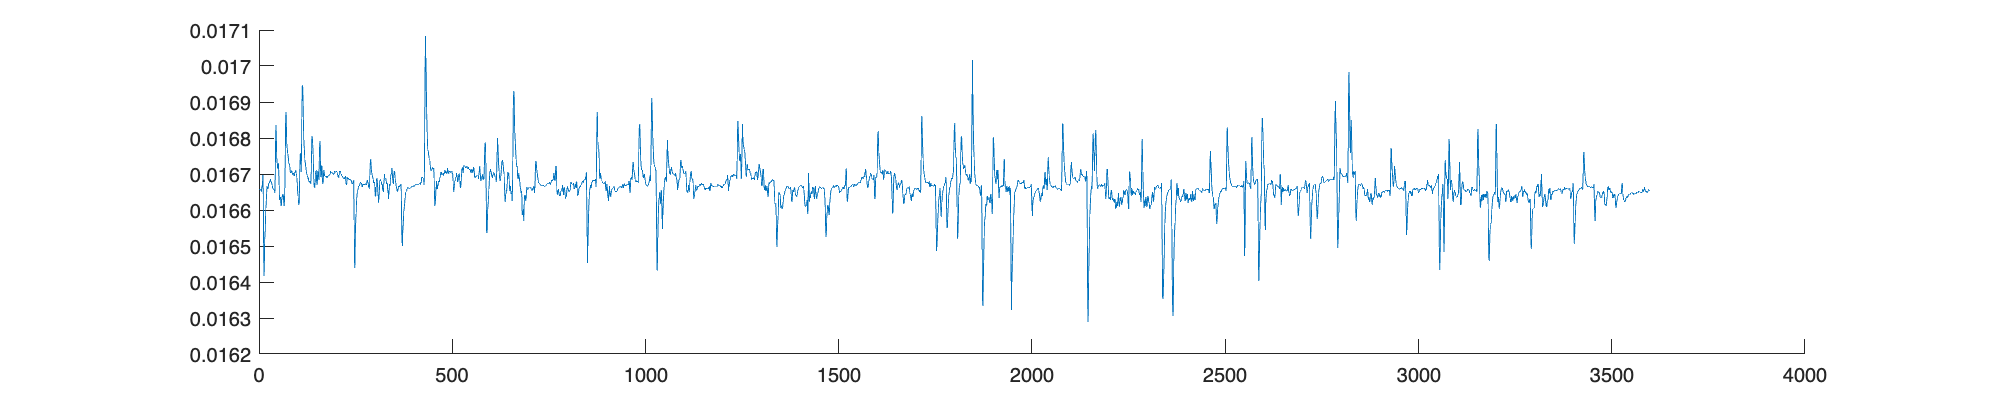

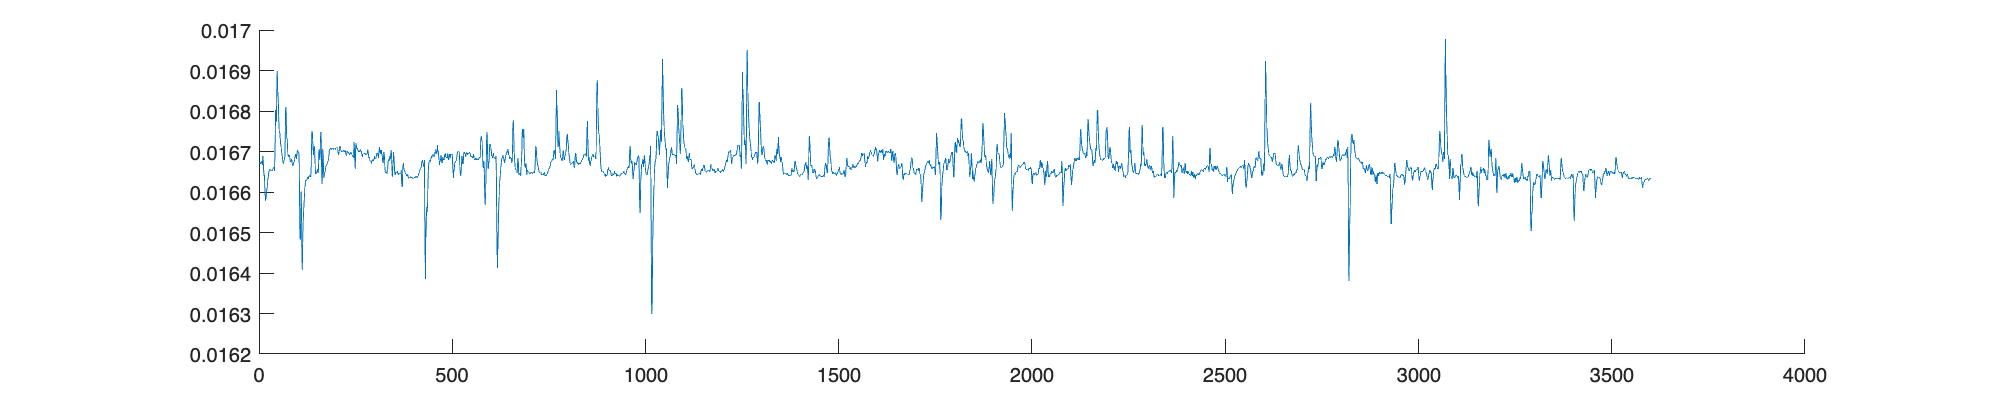


% Plot the temporal activation of the NMF components
figure;
for i = 1:num_components
    figure;
    %subplot(num_components, 1, i);
    set(gcf,'position',[0,0,1000,200]);
    plot(H(i,:));
   %title(['NMF Component ', num2str(i)]);
   %axis ([0 306 -0.04 0.5]);
   box off;
   % f=gcf;
   %  name=strcat(path,['NMF', num2str(i) '.png']);
   %  exportgraphics(f,name,'Resolution',300);
end

%make real image of components

for n=1:num_components

    image_component(n,:,:)=reshape(W(:,n),width,height);

end


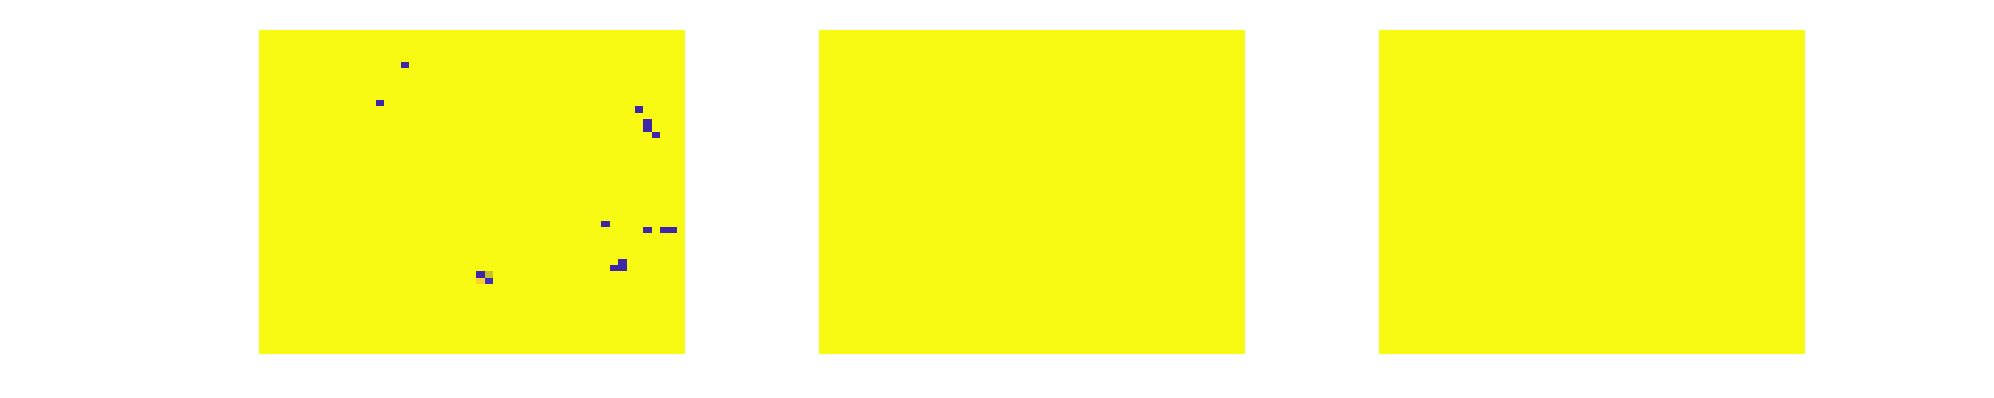

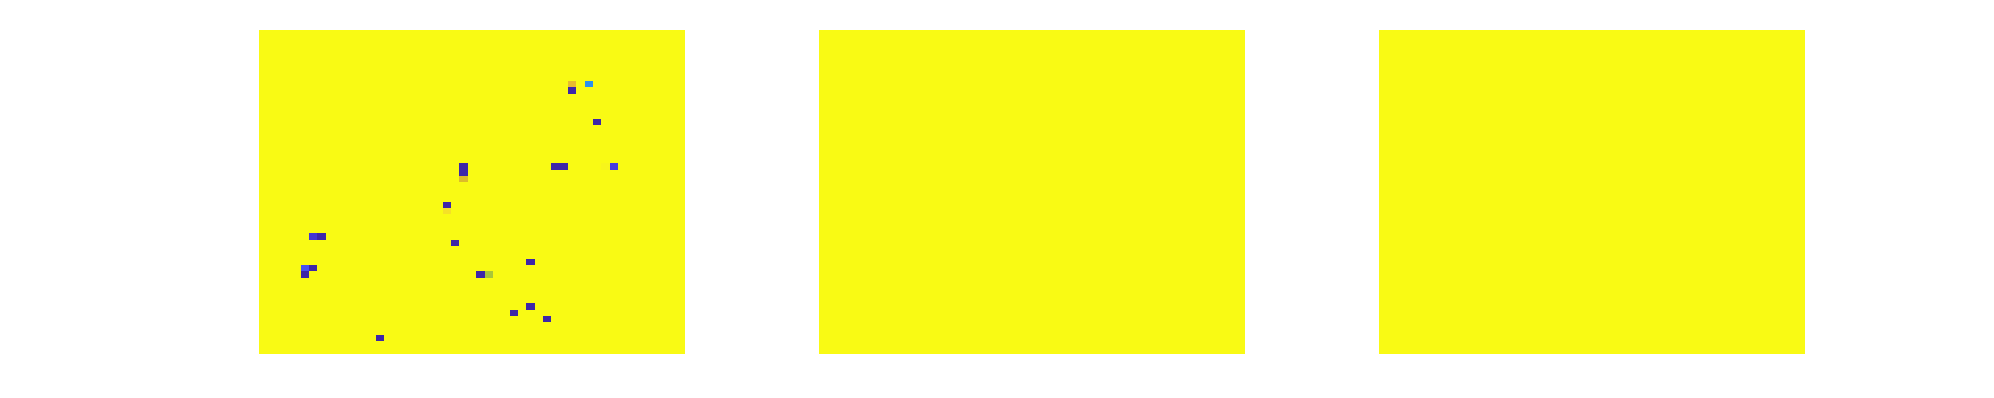

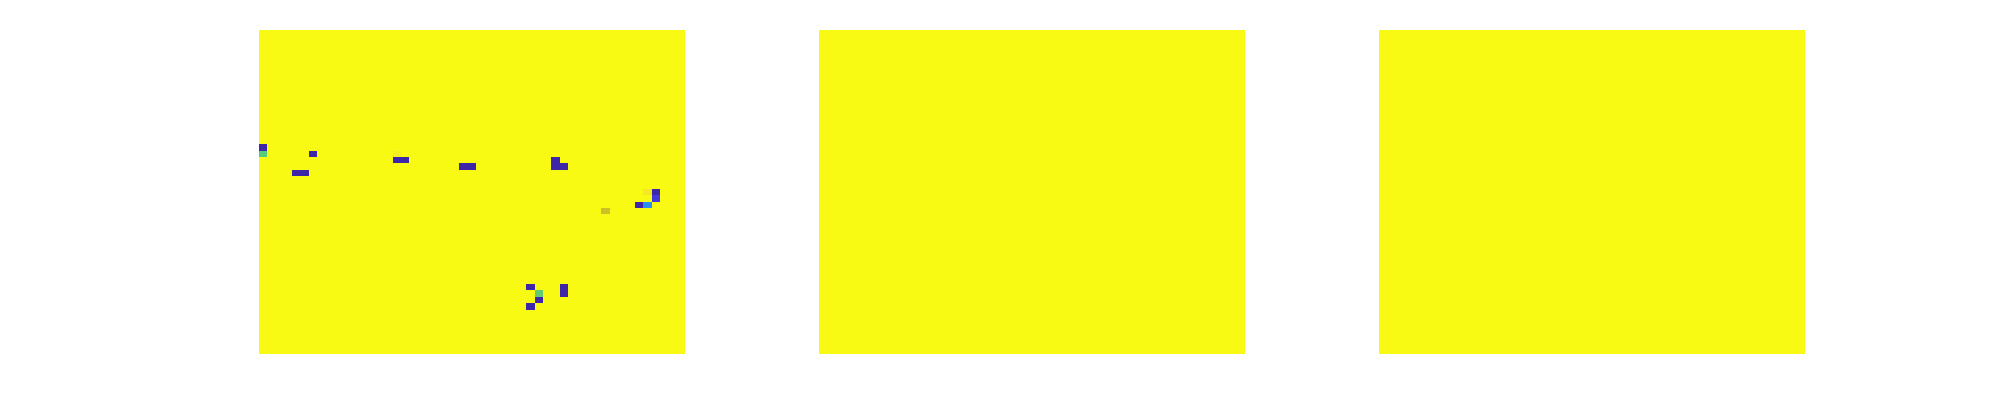

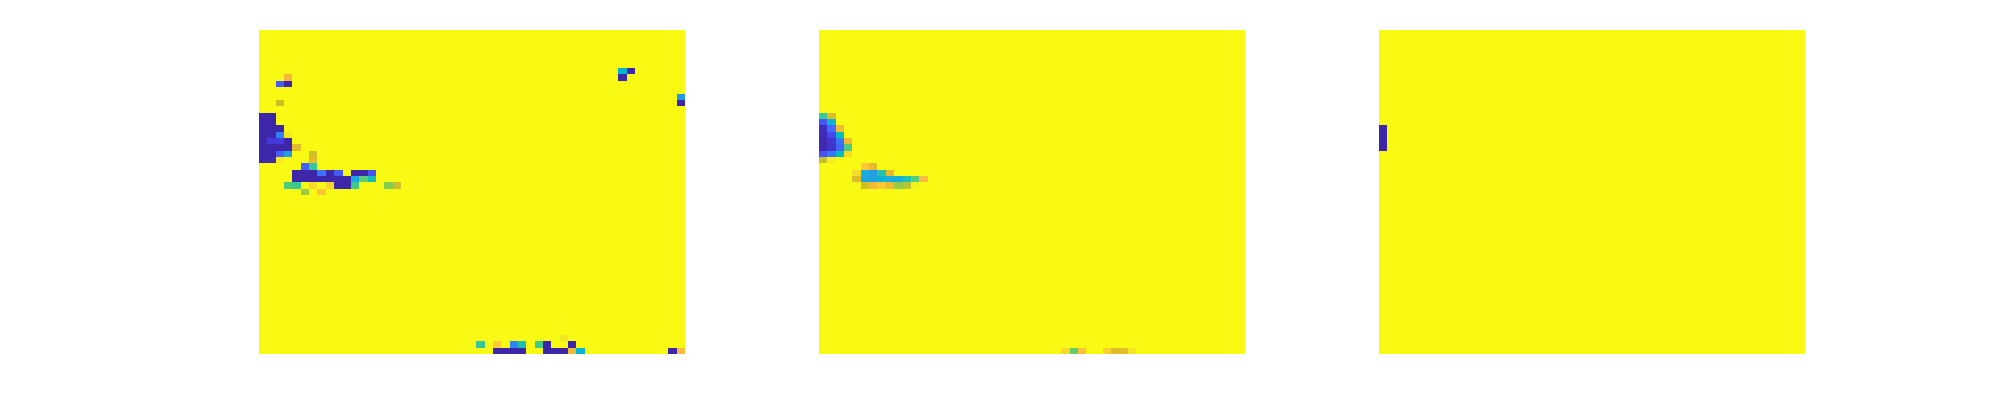

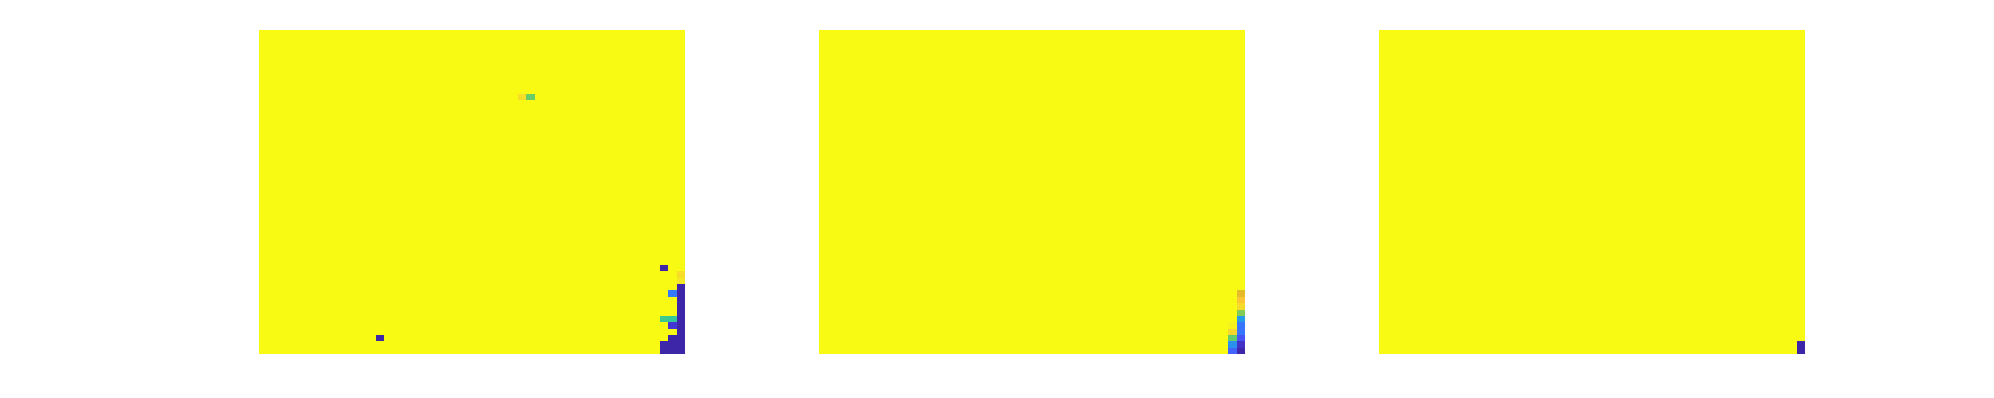

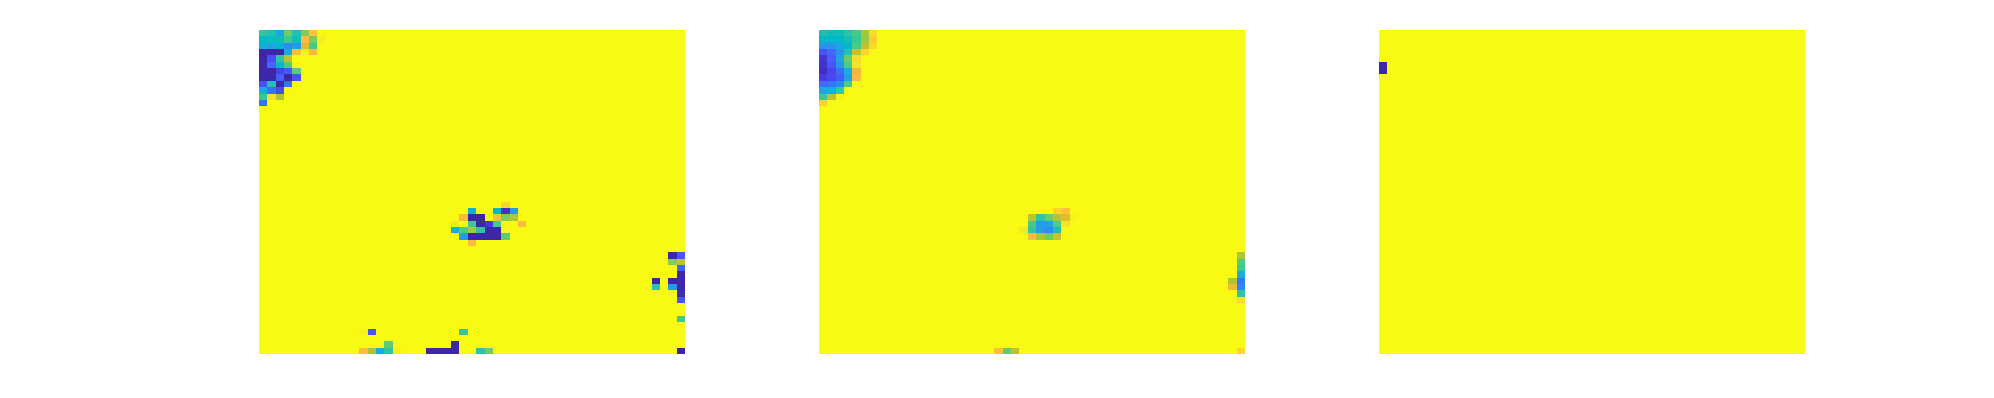

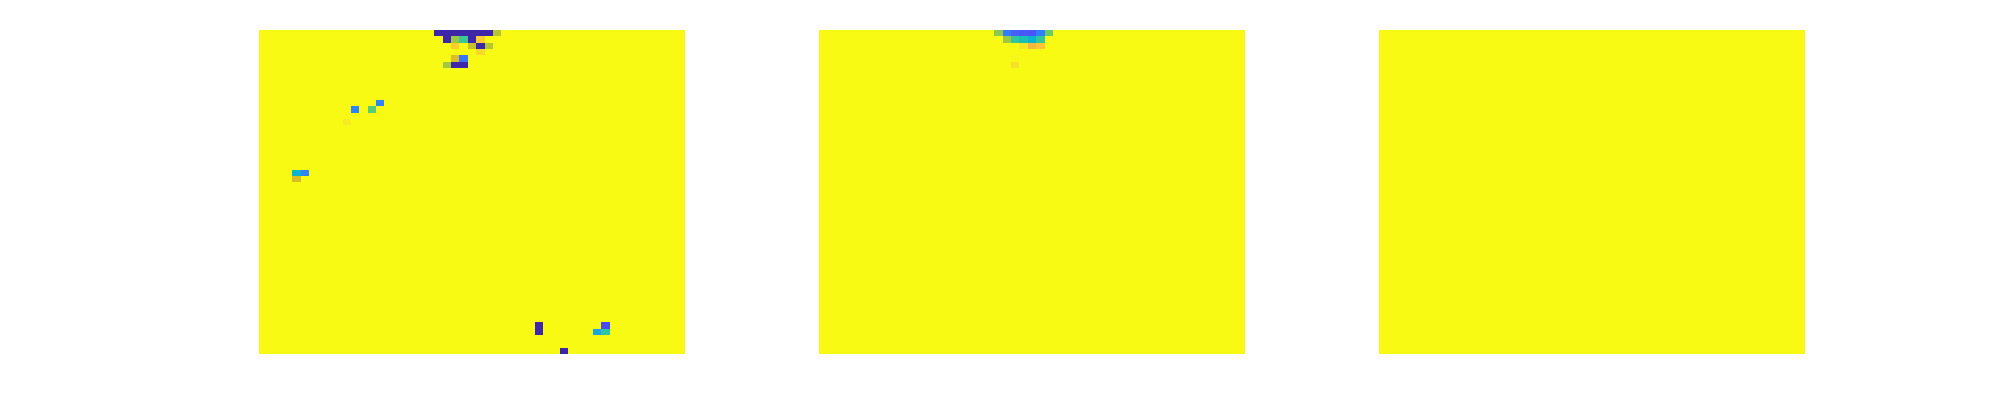

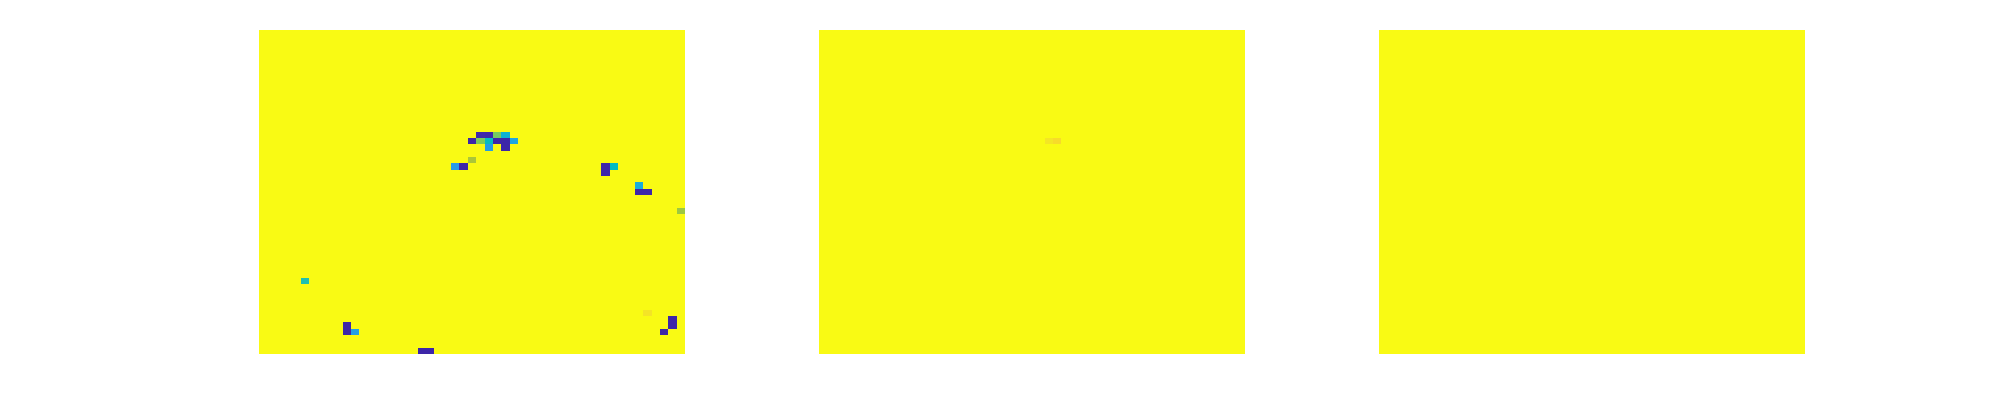


for n=1:num_components

    figure
    set(gcf,'position',[0,0,1000,200]);
    subplot(1,3,1)
    im=squeeze(image_component(n,:,:));
    imagesc(im)
    axis off
    clim ([0 0.2]) 
    im=imgaussfilt(im,1);
    subplot(1,3,2)
    imagesc(im)
    axis off
    clim ([0 0.2]) 
    %level = graythresh(im)
     level=0.01;
    BW = imbinarize(im,level);
    %radius = 50;
    se = strel('disk', 2);
    % se = offsetstrel('ball',5,5);
    BW = imerode(BW,se);
    BW = imdilate(BW,se);
    BW = imclose(BW,se);

    subplot(1,3,3)
    imagesc(BW)
    axis off
    clim ([0 1]) 
    f=gcf;
    name=strcat(path,['NMF', num2str(i) '.png']);
    % exportgraphics(f, name,'Resolution',300);
    labeledImage = bwlabel(BW);
    numObjects = max(labeledImage(:));

end

%[row col]=ind2sub(sz,test);

% Calculate the histogram of the image
% im=squeeze(image_component(1,:,:));
% histogram = imhist(im);
% 
% figure;
% bar(histogram);

% 
% figure
% imagesc(Race(x1,x2),[-1 1.2])
% % axis image
% xlabel('sorted SCE #')     %was RACE
% ylabel('sorted Cell #')
% set(gcf, 'Position', [0, 0, 400, 400]);
% % set(gca, 'YScale', 'log');
% axis tight
% colormap ("jet")
%assembly_sofia

    colors = [
    1 0 0;     % Red
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];

nbassemblies=length(assemblyortho);

Unrecognized function or variable 'assemblyortho'.

n=1
for n=1:nbassemblies
   [subrow, subcol] = ind2sub([55, 55], assemblyortho{n}); 

   cellassembly{n,1} = subrow;
   cellassembly{n,2} = subcol;
end
black=zeros(55,55)
figure
imagesc(black)
colormap (gray)
hold on

for n=1:nbassemblies
    x = cellassembly{n,1}; % X coordinates
    y = cellassembly{n,2}; % Y coordinates
    
    % Combine x and y into a single matrix of points
    points = [x', y'];
    
    % Find the convex hull of the points
    k = convhull(points);
    
    % Sort the vertices in clockwise order
    x_sorted = x(k);
    y_sorted = y(k);
    % plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",colors(n,:))
    patch (x_sorted,y_sorted,colors(n,:))
end
hold off
% for n=2%:nbassemblies
%     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",'r')
% end
% for n=3%:nbassemblies
%     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",'g')
% end


figure
imagesc(black)
colormap (gray)
hold on

for n=1:nbassemblies


    plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",colors(n,:))
    
end
hold off

%measurement size assembly

for n=1:nbassemblies

   area_assembly(n)=length(assemblyortho{n})*size_pixel^2
    
end
mean_area=mean(area_assembly)




